% % Assuming your cell array is called 'dataCellArray'
% i = 1
% active_inputdata_clean = active_inputdata{1,1};
% active_inputdatadata_clean_table_complex = array2table(reshape(active_inputdata_clean, [], 1));
% active_inputdatadata_clean_table_abs = varfun(@abs, active_inputdatadata_clean_table_complex);
% active_inputdatadata_clean_table_dB = varfun(@(x) 20*log10(x), active_inputdatadata_clean_table_abs);


original_data = active_slices_range_doppler{1,73}; % slice 10
modified_data = active_slices_range_doppler{1,73}; 
modified_data (:, 1:5) = 0; % zero the first 5 columns
% max vlaues and indexing
[original_val, original_idx] = max(original_data,[],"all")

original_val = 41.5242

original_idx = 5715

[modified_val, modified_idx] = max(modified_data,[],"all")

modified_val = 41.5242

modified_idx = 5715



%%%
x = inputstructure.range_axis; % x_axis
y = inputstructure.doppler_axis; % .doppler_axis is doppler frequency [Hz] % doppler_velocity_axis; % y_axis
dynamic_range = +inf % +50; % user defined dynamic range to maximise visualisation

dynamic_range = Inf

max_range = 500 % user defined max range to maximise visualisation

max_range = 500

max_doppler = 500 % user defined max doppler to maximise visualisation

max_doppler = 500

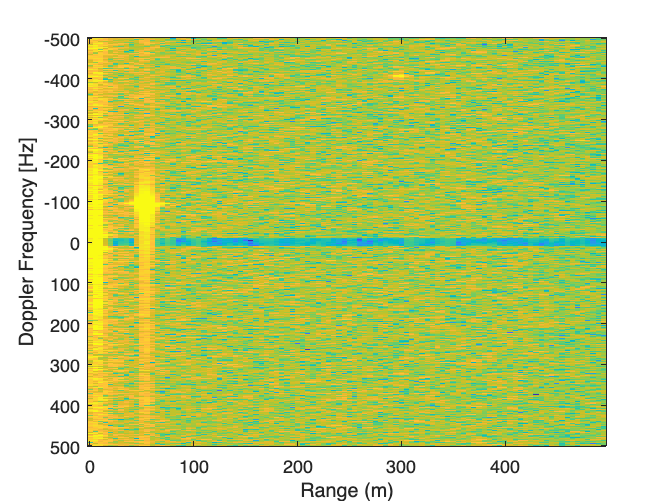


figure
% figure_title = (inputstructure.name + ' Range Doppler Slice ' ...
   %  + k + ' of ' + length(active_inputdata));
fig = figure;
imagesc(x,y,original_data,[-dynamic_range 0])
% title(figure_title);
ylabel('Doppler Frequency [Hz]');
xlabel('Range (m)') ;

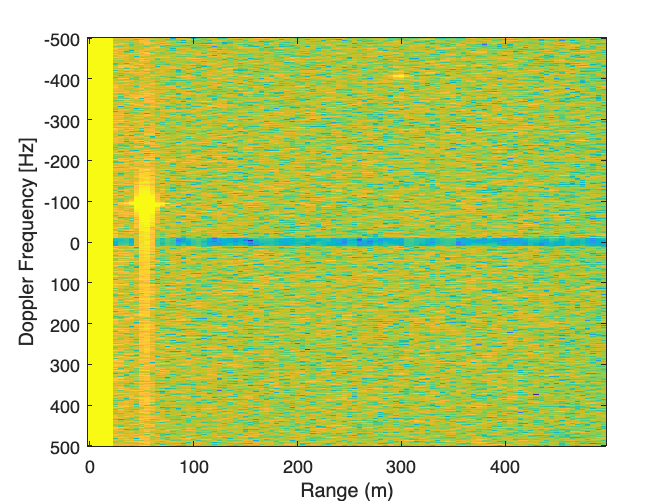


figure
% figure_title = (inputstructure.name + ' Range Doppler Slice ' ...
   %  + k + ' of ' + length(active_inputdata));
fig = figure;
imagesc(x,y,modified_data,[-dynamic_range 0])
% title(figure_title);
ylabel('Doppler Frequency [Hz]');
xlabel('Range (m)') ;

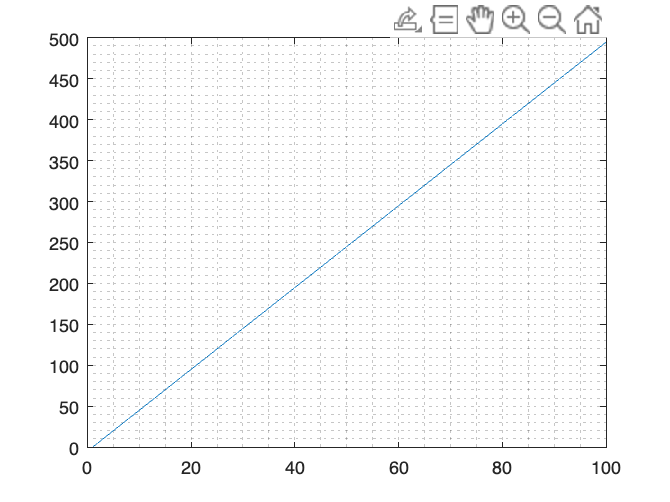


figure

plot(1:length(inputstructure.range_axis), inputstructure.range_axis)
grid minor